Experiment design: central producer colony and a cheater colony a variable distance away, on a uniform field of low-concentration cellulose. Report growth curves for the producer. Use the same parameters that were used in the initial COMETS paper.

	Morphology: Do the colonies develop an irregular shape?

**Claim 1: Colonies increase linearly in diameter over time**

This setup is created by the script *generate_8_2dsim_a.m*

It uses the data file *2d_biodat.mat*

bd = biodat(biodat.initenzymegroup==0,:);
%group 0 is initenz = initbiomass * alpha
%bd = biodat;

%for each time step, count how many cells in the
%slice have biomass > threshold (Default threshold (arbitrary?) = 10^-7
threshold = 10^-14;

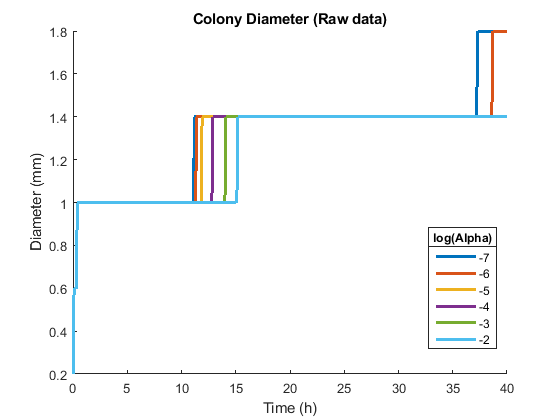

figure();
hold on;
for i = 1:length(bd.biomass)
    biomass = bd.biomass{i};
    b = biomass(biomass.y==25,:); %take a slice
    
    t = sort(unique(biomass.t));
    nsteps = length(t);
    counts = zeros(1,nsteps);
    for j = 1:nsteps
        slice = b.biomass(b.t==t(j));
        scored = slice > threshold;
        counts(j) = sum(scored);
    end
    %plot the results
    plot(t/10,counts/5,'LineWidth',2);
end

xlabel('Time (h)');
ylabel('Diameter (mm)');
leg = legend(num2str(bd.logalpha),'location','best');
title(leg,'log(Alpha)');
title('Colony Diameter (Raw data)');
hold off;

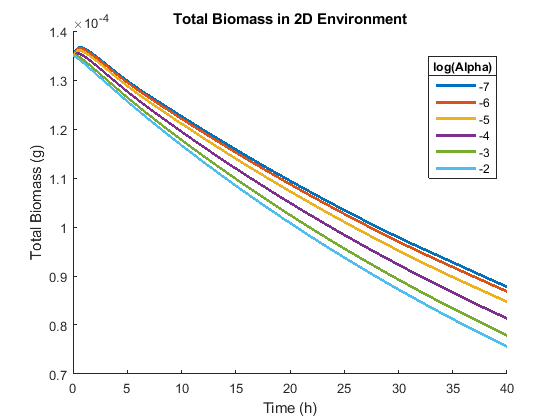

figure();
hold on;
for i = 1:length(bd.biomass)
    biomass = bd.biomass{i};
    b = biomass(biomass.y==25,:); %take a slice
    
    %for each time step, get the total biomass
    t = sort(unique(biomass.t));
    nsteps = length(t);
    totals = zeros(1,nsteps);
    for j = 1:nsteps
        slice = b.biomass(b.t==t(j));
        scored = slice > threshold;
        totalbiomass = sum(slice);
        totals(j) = totalbiomass;
    end
    %plot the results
    plot(t/10,totals,'LineWidth',2);
end

xlabel('Time (h)');
ylabel('Total Biomass (g)');
leg = legend(num2str(bd.logalpha),'location','best');
title(leg,'log(Alpha)');
title('Total Biomass in 2D Environment')
hold off;

Extrapolate from all points to make a continuous function

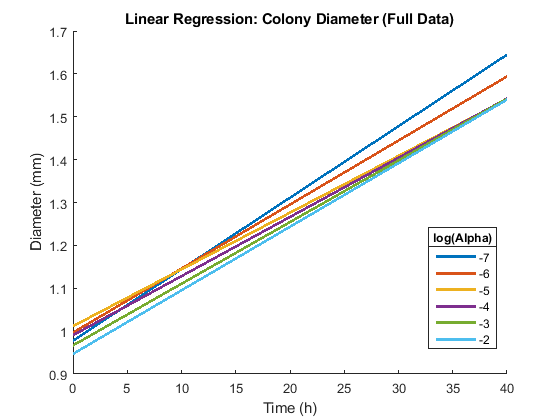

figure();
hold on;
r2_full = zeros(length(bd.biomass),1);
regressions = cell(length(bd.biomass),1);
ms = zeros(length(bd.biomass),1);
bs = ms;
for i = 1:length(bd.biomass)
    biomass = bd.biomass{i};
    b = biomass(biomass.y==25,:); %take a slice
    
    t = sort(unique(biomass.t));
    nsteps = length(t);
    counts = zeros(1,nsteps);
    for j = 1:nsteps
        slice = b.biomass(b.t==t(j));
        scored = slice > threshold;
        counts(j) = sum(scored);
    end
    
    %pad counts with ones to get the intercept
    X = [ones(length(t),1),t];
    
    r = X\counts';
    regressions{i} = r;
    ms(i) = r(2);
    bs(i) = r(1);
    ycalc = X*r;
    plot(t/10,ycalc/5,'LineWidth',2);
    
    r2_full(i) = 1 - sum((counts' - ycalc).^2)/sum((counts' - mean(counts)).^2);
end

xlabel('Time (h)');
ylabel('Diameter (mm)');
leg = legend(num2str(bd.logalpha),'location','best');
title(leg,'log(Alpha)');
title('Linear Regression: Colony Diameter (Full Data)');
hold off;

rtab = table();
rtab.logalpha = num2str(bd.logalpha);
rtab.b0 = bs/5;
rtab.b1 = ms/5

rtab = 6×3 table
    logalpha      b0          b1    
    ________    _______    _________
       -7       0.97773    0.0016675
       -6       0.99658    0.0014934
       -5        1.0117     0.001323
       -4       0.99034      0.00138
       -3       0.96667    0.0014385
       -2       0.94685    0.0014827

Extrapolate from the points where the jumps happen to make a continuous function.

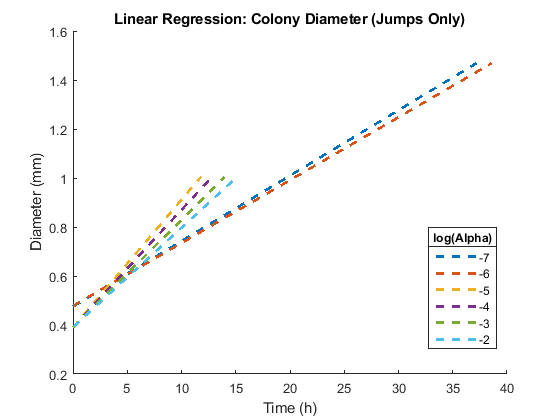

figure();
hold on;
r2_jumps = zeros(length(bd.biomass),1);
regressions = cell(length(bd.biomass),1);
ms = zeros(length(bd.biomass),1);
bs = ms;
for i = 1:length(bd.biomass)
    biomass = bd.biomass{i};
    b = biomass(biomass.y==25,:); %take a slice
    
    t = sort(unique(biomass.t));
    nsteps = length(t);
    counts = zeros(1,nsteps);

    for j = 1:nsteps
        slice = b.biomass(b.t==t(j));
        scored = slice > threshold;
        counts(j) = sum(scored);
    end
    
    %pare down the data
    jumps = find(counts(2:end) > counts(1:end-1));
    t = t(jumps);
    origcounts = counts;
    counts = counts(jumps);
    
    %pad counts with ones to get the intercept
    X = [ones(length(t),1),t];
    
    r = X\counts';
    regressions{i} = r;
    ms(i) = r(2);
    bs(i) = r(1);
    ycalc = X*r;
    plot(t/10,ycalc/5,'--','LineWidth',2);
    
    r2_jumps(i) = 1 - sum((counts' - ycalc).^2)/sum((counts' - mean(counts)).^2);

end

xlabel('Time (h)');
ylabel('Diameter (mm)');
leg = legend(num2str(bd.logalpha),'location','best');
title(leg,'log(Alpha)');
title('Linear Regression: Colony Diameter (Jumps Only)');
hold off;


rtab = table();
rtab.logalpha = num2str(bd.logalpha);
rtab.b0 = bs/5;
rtab.b1 = ms/5

rtab = 6×3 table
    logalpha      b0          b1    
    ________    _______    _________
       -7       0.47552    0.0026706
       -6       0.47778    0.0025675
       -5        0.3897    0.0052139
       -4       0.39052    0.0047973
       -3       0.39134    0.0043775
       -2       0.39198    0.0040524

r2_full

r2_full =     0.6804
    0.6374
    0.6020
    0.6318
    0.6628
    0.6866


r2_jumps

r2_jumps =     0.8172
    0.8139
    0.7691
    0.7676
    0.7661
    0.7649



r2_full - r2_jumps

ans =    -0.1368
   -0.1765
   -0.1671
   -0.1357
   -0.1032
   -0.0783


The Regression shows that we can safely say the growth is linear for *small* alphas over the observed time frame, but when alpha is large the growth appears to slow down over time.

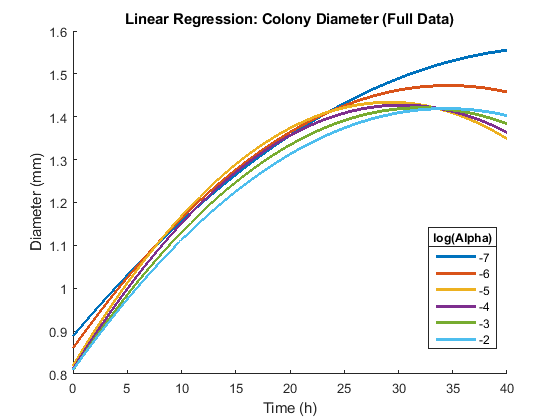

%Do the regression with D = c + a*X + b*X^2

figure();
hold on;
r2_sq = zeros(length(bd.biomass),1);
regressions = cell(length(bd.biomass),1);
b0 = zeros(length(bd.biomass),1);
b1 = zeros(length(bd.biomass),1);
b2 = zeros(length(bd.biomass),1);
for i = 1:length(bd.biomass)
    biomass = bd.biomass{i};
    b = biomass(biomass.y==25,:); %take a slice
    
    t = sort(unique(biomass.t));
    t2 = t/10;
    nsteps = length(t2);
    counts = zeros(1,nsteps);
    for j = 1:nsteps
        slice = b.biomass(b.t==t(j));
        scored = slice > threshold;
        counts(j) = sum(scored);
    end
    
    %pad counts with ones to get the intercept
    X = [ones(length(t),1),t,ones(length(t),1)];
    X(:,3) = t2.*t2;
    counts = counts/5;
    r = X\counts';
    regressions{i} = r;
    b0(i) = r(1);
    b1(i) = r(2);
    b2(i) = r(3);
    ycalc = X*r;
    plot(t2,ycalc,'LineWidth',2);
    
    r2_sq(i) = 1 - sum((counts' - ycalc).^2)/sum((counts' - mean(counts)).^2);
end

xlabel('Time (h)');
ylabel('Diameter (mm)');
leg = legend(num2str(bd.logalpha),'location','best');
title(leg,'log(Alpha)');
title('Linear Regression: Colony Diameter (Full Data)');
hold off;


tab = table();
tab.logalpha = bd.logalpha;
tab.b0 = b0;
tab.b1 = b1;
tab.b2 = b2

tab = 6×4 table
    logalpha      b0          b1            b2     
    ________    _______    _________    ___________
       -7       0.88815    0.0030145    -0.00033675
       -6       0.86041     0.003541     -0.0005119
       -5       0.81918    0.0042181    -0.00072378
       -4       0.81174    0.0040657    -0.00067142
       -3       0.80823    0.0038209    -0.00059561
       -2        0.8097    0.0035451     -0.0005156


r2_full

r2_full =     0.6804
    0.6374
    0.6020
    0.6318
    0.6628
    0.6866


r2_sq

r2_sq =     0.7101
    0.7177
    0.7951
    0.7922
    0.7847
    0.7756


r2_sq - r2_full

ans =     0.0297
    0.0803
    0.1931
    0.1603
    0.1218
    0.0890


%It's a better fit for low alphas, but doesn't tip anything new into the level of significance
%r(3) = -1.0377e-05
